# Running a ray trace calculation

The ray trace model includes field-height and wavelength dependent point spread functions. These can either be created synthetically, or they can be derived from optics software, such as Zemax. 

See also: 

   s_opticsRTGridLines, t_oiCompute, rtImportData

ieInit

## Make an example scene radiance of points

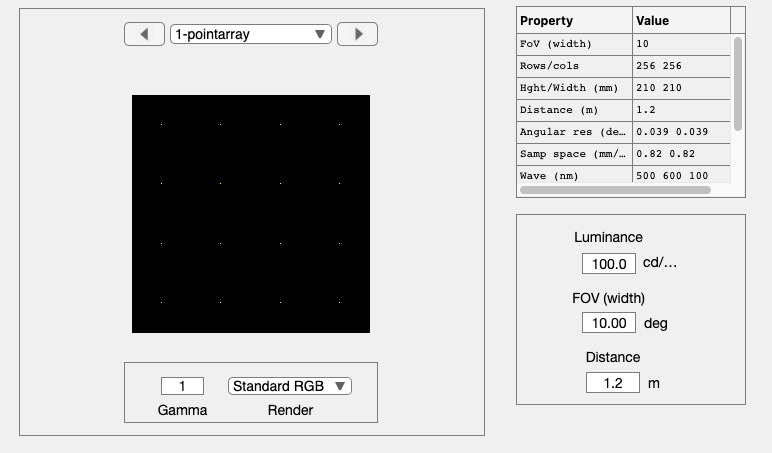

% You can adjust these parameters to speed up the calculation or
% explore the lens properties
sz = 256; spacing = 64;
scene = sceneCreate('point array',sz,spacing);   % Creates an array of points
scene = sceneSet(scene,'fov',10);                % Make this smaller after MH agrees.

% To speed the computatons we use a small number of wavelength samples
scene = sceneInterpolateW(scene,(500:100:600));

% Add the scene to the ISET database and view it
sceneWindow(scene); drawnow;

## Create an optical image (oi) that uses the default ray trace model

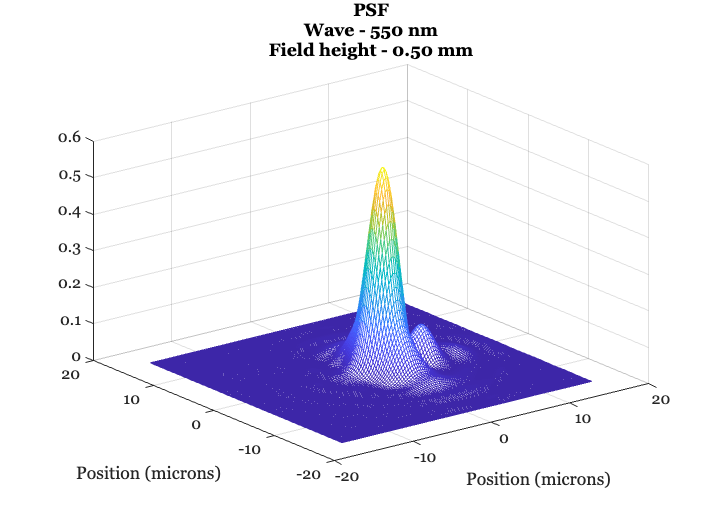

% This model is a lens we converted from Zemax to the array of point
% spread functions.  There are various functions that illustrate how
% to take Zemax data and convert them to the ISETCam ray trace
% format.
oi = oiCreate('ray trace');

% Here is an example of one of the PSF
wave = 550; fhmm = 0.5;
rtPlot(oi,'psf',wave,fhmm);


% Confirm that the optics model type is set to ray trace
% In general, optics parameters can be read out with this syntax using an
% oiGet() call.
fprintf('Optics model:       %s\n',oiGet(oi,'optics model'))

Optics model:       raytrace


fprintf('Ray trace lens:     %s\n',oiGet(oi,'optics rt name'))  % Name of the lens used by ray trace

Ray trace lens:     Asphere 2mm


## The oiCompute will call opticsRayTrace to do the computation

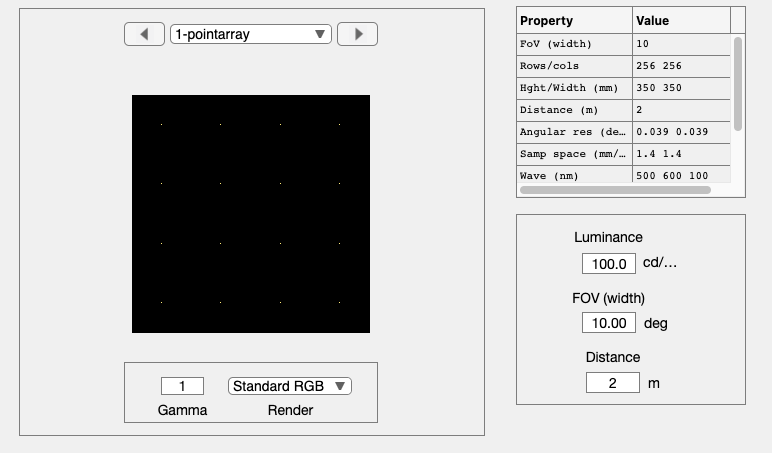

Geometric distortion ...
Pre-computing PSFs...Setting up for scene pointarray
Eccentricity bands: 0.000 (um)
Eccentricity bands: 51.825 (um)
Eccentricity bands: 103.650 (um)
Eccentricity bands: 155.475 (um)
Eccentricity bands: 207.300 (um)
Eccentricity bands: 259.125 (um)
PSF sample grid: 23 by 23
Done precomputing PSFs.
Applying PSFs.
6 eccentricity bands
Done applying PSFs.


% We do use 'crop' because there is no point in having the black
% border around this scene.
oi = oiCompute(oi,scene,'crop',true);

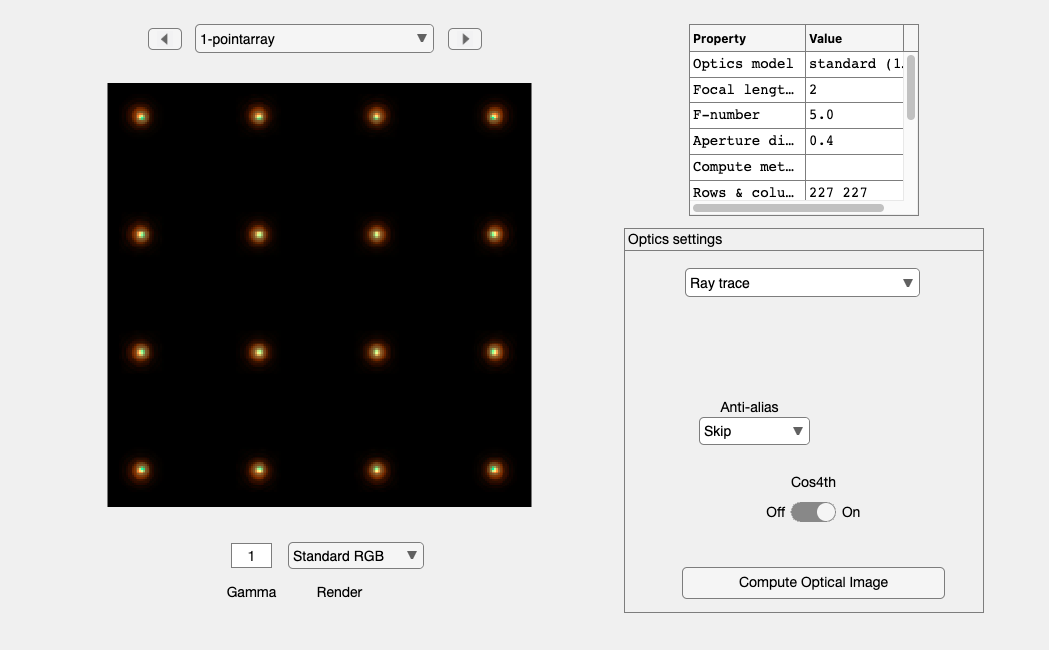


% Here is the rendered blurred result
oiWindow(oi);